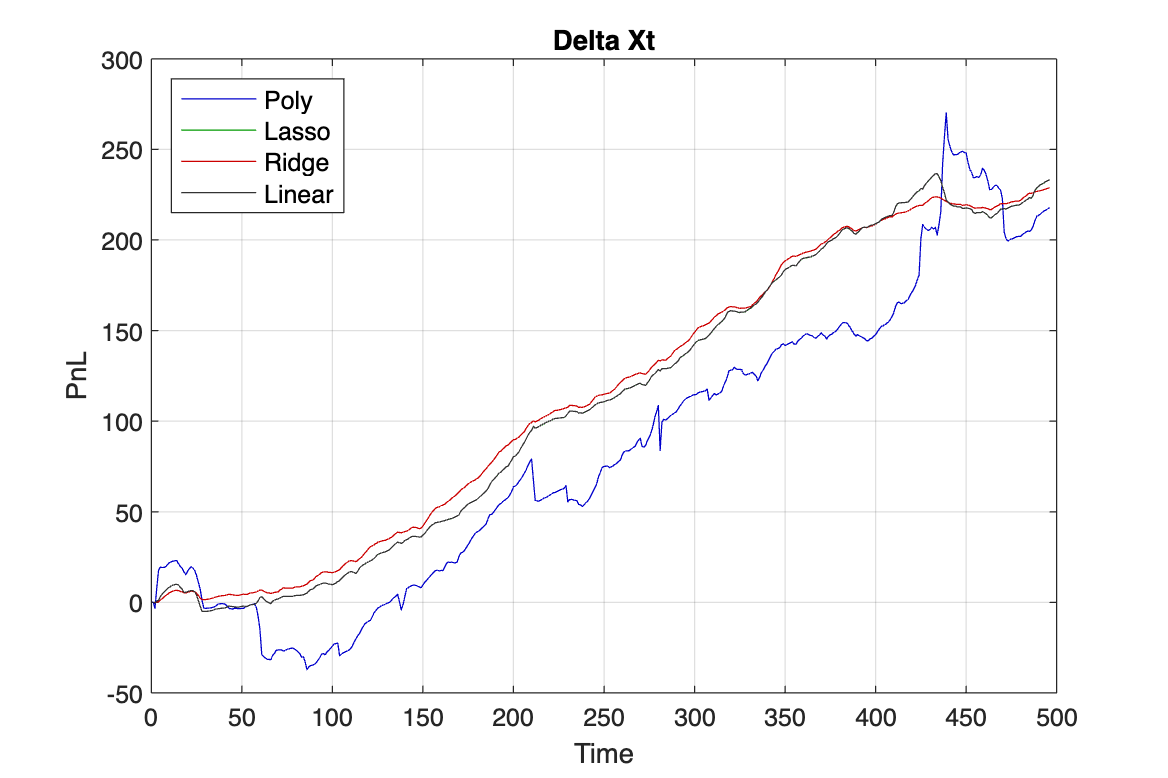

% Read the CSV file
data = readtable('Delta_xt.csv');

poly_values = data.poly;
lasso_values = data.lasso;
ridge_values = data.ridge;
linear_values = data.Linear;

figure('Position', [100, 100, 1500, 1000]);

% Plot the data
plot(poly_values,  'DisplayName', 'Poly', 'Color', [0, 0, 0.8]);
hold on;
plot(lasso_values,  'DisplayName', 'Lasso', 'Color', [0, 0.6, 0]);
plot(ridge_values,  'DisplayName', 'Ridge', 'Color', [0.8, 0, 0]);
plot(linear_values,  'DisplayName', 'Linear', 'Color', [0.2, 0.2, 0.2]);
hold off;

% Add labels and legend
title('Delta Xt');
xlabel('Time'); 
ylabel('PnL');
legend('show');
legend('Location', 'Northwest', 'FontSize', 10);
% Display the grid
grid on;